# Compression

## About Compression

Compression is a non-linear dynamic processing technique used to control and manipulate the dynamic range of an audio signal. Typical compressors reduce the dynamic range between the loudest and softest parts. This process is crucial in post-production for maintaining a consistent and balanced sound. Various types of dynamic processing effects, such as expanders, limiters, noise gates, dynamic EQs, and multiband compressors, serve different purposes in shaping and refining the audio (Vincent, 2012).

## History of compression

The first compressor designed was a limiter in the 1930s, during the development of radio networks. Issues occurred during the broadcast and transmission of audio signals, where the audio would start to overmodulate due to levels exceeding a certain threshold, distorting the signal (Carter, 2022).

These early compressors replaced manual fader riding because they were more consistent and performed with higher accuracy, reducing the risk of accidentally damaging equipment, clipping, or distorting the signal (Carter, 2022). One of the earliest known examples of a limiter is the *Level-Loc*, designed by brothers Les and Larry Gelb in the 1940s.

In the early 1960s, compressors gained popularity in the music industry, and the demand for more sophisticated dynamic control arose. Compressors like the *Teletronix LA-2A *introduced a ratio parameter to allow users to dial in the amount of compression, unlike limiters, which had a constant static ratio of infinity.

Towards the 1970s, multiband compressors started to be developed. This was because mono-band compressors could create unwanted artifacts, such as reduced low-frequency content. One of the first multiband compressors designed was the *DAP310*, designed by the 'Maxx Brothers', Mike and Evan Dorrough (Somich, 2018). Other iconic compressors of the time included the *UREI 1176* and the *DBX 160*.

In the 1980s, hybrid digitally controlled compressors, such as the *Gentner Audio Prism*, started to be designed. Into the 90s, with the evolution of microprocessors, fully digitalised compressors, such as the *Omnia FM* and *Orban Optimod FM 8200*, were designed (Cherubini, 2022).

## Compressor Types

Throughout the history of compressors, there are various types of designs for different purposes and applications.

**Optical Compressors**

Optical compressors use a light-dependent resistor (LDR) and a light source to control the compression (Fox, 2021a). They are known for their smooth and musical compression characteristics, often used for vocals and instrument tracks. They have a history dating back to the mid-20th century with *UA LA2A* compressors gaining popularity.

**Variable-Mu Compressors**

Variable-Mu compressors, or tube compressors, operate by changing the tube's gain based on the input level. They are known for their smooth and musical compression, often used in mastering (Paquis, 2023). These were developed around the mid-20th century as well.

**Tube Compressors**

Tube compressors use vacuum tubes in their circuitry. They are prized for their warm and vintage sound. Tube compressors can add harmonic distortion, creating a pleasing coloration to the audio signal (McCoy, 2022). These have been in use since the mid-20th century.

**VCA (Voltage-Controlled Amplifier) Compressors**

VCA compressors use a voltage-controlled amplifier to adjust the gain of an audio signal. They are known for their accuracy and transparency, making them suitable for a wide range of applications. VCA compressors became popular in the late 1960s and 1970s as semiconductor technology advanced (Soundbridge.io, 2023).

**FET (Field-Effect Transistor) Compressors**

FET compressors use transistors to control the gain. They are known for their fast attack times and are often favored for their aggressive and punchy sound. These gained popularity in the 1960s and 1970s, with the *UREI 1176* being a notable example (Fox, 2021b).

**Digital Software Compressors**

With the advancement of digital technology and Digital Audio Workstations (DAW), Virtual Studio Technology (VST) plugins started to become popular. Traditional hardware such as compressors, limiters and other dynamic processing units found their virtual equivalents emulated with Digital Signal Processing (DSP) techniques. Effects such as expanders emerged, to complement compressors, enabling the user to increase the dynamic range of a signal. Noise gates evolved to efficiently eliminate unwanted background noise during silent passages (Brown, 2021). These were also heavily used in the 80s as a creative mixing choice, being added onto reverb busses to create the famous 'gated reverb' effect. Upwards compression was also introduced, which enhances subtle details; emphasising transients by selectively boosting quieter elements, providing a controlled and transparent dynamic manipulation.

Below shows typical static characteristics of dynamic processing effects:

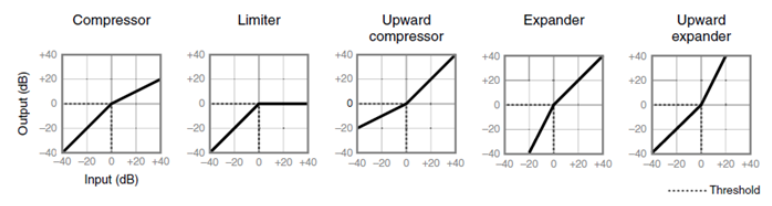

Dynamics processing utilizes an envelope follower for amplitude detection, extracting a gain factor through a static curve. A smoothing filter ensures gradual gain changes, and a multiplier assigns weight to the input signal (see the figure below). Optionally, the input signal may undergo delay to compensate for side chain delays. The gain factor is usually derived from the input signal, but the side chain can also control it by connecting to another signal (Zölzer, 2011).

There are various types of peak detection including the use of a full-wave rectifier combined with an AR-averager (Figure 4.9) with a brief attack time for tracking the signal's peak value. Alternatively, employing a squarer averaged with a single time constant (4.10) yields the RMS value, offering a measure of the signal's power.

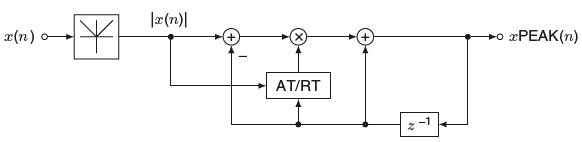

***Peak  Detector / Follower***

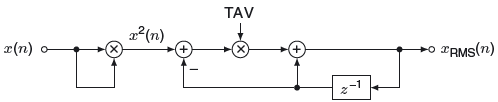

***RMS Detector / Follower***

**Feed-forward and feed-back compressors.**

## Limiters and Compressors

### Equations

To perform the limiting compression onto the input signal $x$, you first need to convert the signal from magnitude into dB.


$$x_{\mathrm{dB}}[n]=20 \times \log _{10}|x[n]|$$


However, $20\times \log_{10} \;|x\left\lbrack n\right\rbrack =0|$ would return $-\inf$. Therefore in the conversion between magnitude and decibels, we replace $-\inf$ by a substitute value such as -120dB.

The $x_{\textrm{dB}}$ values then pass through the gain computer which will apply the static characteristic. This checks where the dB values are in relation to the threshold $T$ and the knee width$W$:


$$x_{\mathrm{sc}}\left(x_{\mathrm{dB}}\right)=\left\{\begin{array}{cc}
x_{\mathrm{dB}} & x_{\mathrm{dB}}<\left(T-\frac{W}{2}\right) \\
x_{\mathrm{dB}}-\frac{\left(x_{\mathrm{dB}}-T+\frac{W}{2}\right)^2}{2 W} & \left(T-\frac{W}{2}\right) \leq x_{\mathrm{dB}} \leq\left(T+\frac{W}{2}\right) \\
T & x_{\mathrm{dB}}>\left(T+\frac{W}{2}\right)
\end{array},\right.$$


If a hard knee is applied (i.e. $W=0$) then we can use the following equation instead:


$$x_{\mathrm{sc}}\left(x_{\mathrm{dB}}\right)=\left\{\begin{array}{cl}
x_{\mathrm{dB}} & x_{\mathrm{dB}}<T \\
T & x_{\mathrm{dB}} \geq T
\end{array}\right.$$


The gain reduction is then calculated using the computed gain values minus the input dB values:


$$g_{\mathrm{c}}[n]=x_{\mathrm{sc}}[n]-x_{\mathrm{dB}}[n]$$


These computed gain values are then smoothed with an envelope consisting of the attack and release time coefficients, $a_A$ being the attack coeff and $a_R$ being the realease coeff. Interpolation is used to perform this smoothing:


$$g_{\mathrm{s}}[n]= \begin{cases}\alpha_{\mathrm{A}} g_{\mathrm{s}}[n-1]+\left(1-\alpha_{\mathrm{A}}\right) g_c[n], & g_{\mathrm{c}}[n] \leq g_{\mathrm{s}}[n-1] \\ \alpha_{\mathrm{R}} g_{\mathrm{s}}[n-1]+\left(1-\alpha_{\mathrm{R}}\right) g_c[n], & g_{\mathrm{c}}[n]>g_{\mathrm{s}}[n-1]\end{cases}$$


Using the attack and release parameters, we can calculate these $a$ coefficients by passing in the time in seconds as $T_t$:


$$\alpha_{\mathrm{t}}=\exp \left(\frac{-\log (9)}{F s \times T_{\mathrm{t}}}\right)$$


After applying the smoothing filter, the makeup gain is applied. If the auto make up gain parameter is set to true, the makeup gain will be automatically calculated based on a 0dB target input:


$$M=-x_{\mathrm{sc}}\left(x_{\mathrm{dB}}=0\right)$$



$$g_{\mathrm{m}}[n]=g_{\mathrm{s}}[n]+M$$


The calculated gain values are then converted from decibels into linear magnitude:


$$g_{\text {lin }}[n] = 10 ^{\left(\frac{g_{\text {m}[n]}}{{20}}\right)}$$


These linear gain values are then multiplied by the original signal to apply the gain reduction with makeup gain:


$$y[n]=x[n] \times g_{\text {lin }}[n]$$


### Applying the limiter

Below shows the code to generate a custom limiter object from the AudioDynamicRangeLimiter class.

This first part of the code reads in the audio to show how the compression can be applied to an audio signal.

% Clear the workspace, command window and figures
clear; clc; clf;

% Reading in the audio samples from the audio file
[in, fs] = audioread("audio/guitar.wav");
x = in(:, 1)';                              % transposing the audio so it's the correct dimention, and making the audio mono
%x = 1/max(abs(x)) .* x;                     % Normalise the signal so it shows better on the graph

#### Parameters

This next section of the code sets the parameters for the compression.

% Setting the compression parameters
threshold = -32.54;
knee = 10.89;
attack = 0.13;
release = 0.19;
makeupGainAuto = true;
makeupGain =3.95;

These parameters are then passed into the AudioDynamicRangeLimiter class to create a custom object.

% Passing these parameters into the custom limiter class to create an
% audio dynamic range limiter object
adrl = AudioDynamicRangeLimiter( ...
    threshold, ...
    knee, ...
    attack, ...
    release, ...
    makeupGainAuto, ...
    makeupGain);

**Threshold**

- **Compression**: The threshold in a compressor determines the level at which compression begins to take effect. Any signal that surpasses this threshold will be subject to compression.

- **Limiter**: In a limiter, the threshold is an absolute level beyond which the signal is not allowed to pass. The limiter engages to prevent the signal from exceeding this predefined level.

**Ratio**

- **Compression**: The ratio represents the amount of compression applied to the signal once it exceeds the threshold. For example, a 4:1 ratio means that for every 4 dB the input signal exceeds the threshold, the output will only increase by 1 dB.

- **Limiter**: In a limiter, the ratio is extremely high, often denoted as infinity (inf:1), indicating a brick-wall limiting effect where any signal exceeding the threshold is reduced to the threshold level.

**Knee**

The knee controls how abruptly the compressor reacts when the signal crosses the threshold. A "soft knee" has a gradual onset of compression, smoothly applying compression as the signal approaches the threshold. In contrast, a "hard knee" results in an abrupt, more noticeable compression onset.

The static characteristic can show how the compression is applied to the audio when the signal passes the given threshold.

% Plot the static characteristic of the limiter object, passing in a
% reference to the limiter's static characteristic method which calculates
% the gain reduction
plotStaticCharacteristic(@adrl.applyStaticCharacteristic);

**Attack Time** 

The attack time determines how quickly the compressor responds to a signal once it crosses the threshold. A shorter attack time means the compressor reacts quickly, suitable for controlling fast transients. A longer attack time allows some transients to pass through uncompressed, useful for preserving the natural dynamic of certain instruments.

**Release Time**

Release time controls how long it takes for the compressor to stop compressing after the input signal falls below the threshold. A shorter release time can result in a more aggressive, pumping sound, while a longer release time may produce smoother compression.

The plot shows a basic demonstration of how the attack and release times are applied to the signal.

% Plotting the attack and release stages of the compression with an example
% 4kHz sine wave input signal
plotAttackReleaseCharacteristics(attack, release, threshold);

**Make Up Gain Mode**

Make-up gain compensates for the reduced level of the compressed signal. In some compressors, there may be different modes for make-up gain, such as "automatic" or "manual." Automatic mode adjusts the gain automatically based on the amount of compression applied, while manual mode allows the user to set the make-up gain manually.

**Make Up Gain**

Make-up gain is the amount of gain applied to the compressed signal to bring its level back to a desired or perceptually balanced level. It compensates for the reduced volume caused by the compression process, allowing the user to maintain a consistent output level.

**Sidechain**

Side chain is used in dynamic processing to control the level of the input signal, via passing the sidechain into the level detection stages of the processing chain. This means that the input signal may only be compressed when the sidechain input exceeds the threshold.

#### Processing the audio

The audio can then be sent to the process method of the compressor object to apply the compression.

% Passing the audio into the process method to apply the limiter's effect
% on the audio samples
[compressed_audio, g] = adrl.process(x, fs);

The plotTimeDomainSignals function can then display in the time domain the differences between each signal.

% Plot the original and compressed signals in the time domain
plotTimeDomainSignals(x, compressed_audio, fs);

The compressor uses a gain computer to calculate the gain reduction to apply to the signal. This is returned as g from the process method and can be plotted to show the gain reduction.

% Plot the gain computer of the limiter object, passing in the
% calculated gain reduction
plotGainComputer(g);

#### Playing the audio

Press play to hear the original signal.

 
sound(x, fs);

Press play to hear the compressed signal.

 
sound(compressed_audio, fs);

## Compression

### Equations

Below demonstrates how to modify the equations shown above to apply the ratio value in the static characteristic calculation on the gain computer section:


$$x_{\mathrm{sc}}\left(x_{\mathrm{dB}}\right)=\left\{\begin{array}{cc}
x_{\mathrm{dB}} & x_{\mathrm{dB}}<\left(T-\frac{W}{2}\right) \\
x_{\mathrm{dB}}+\frac{\left(\frac{1}{{R}}-1\right)\left(x_{\mathrm{dB}}-T+\frac{W}{2}\right)^2}{2 W} & \left(T-\frac{W}{2}\right) \leq x_{\mathrm{dB}} \leq\left(T+\frac{W}{2}\right) \\
T + \left(\frac{X_{\text {dB}}-T}{{R}}\right) & x_{\mathrm{dB}}>\left(T+\frac{W}{2}\right)
\end{array},\right.$$


The same applies for the hard knee equation, applying the ratio value:


$$x_{\mathrm{sc}}\left(x_{\mathrm{dB}}\right)=\left\{\begin{array}{cl}
x_{\mathrm{dB}} & x_{\mathrm{dB}}<T \\
T+{\left(\frac{X_{\text {dB}}-T}{{R}}\right)} & x_{\mathrm{dB}} \geq T
\end{array}\right.$$


### Applying the Compressor

The code below demonstrates a compressor object being created.

This now accepts a ratio value as can be seen on the static characteristic plot.

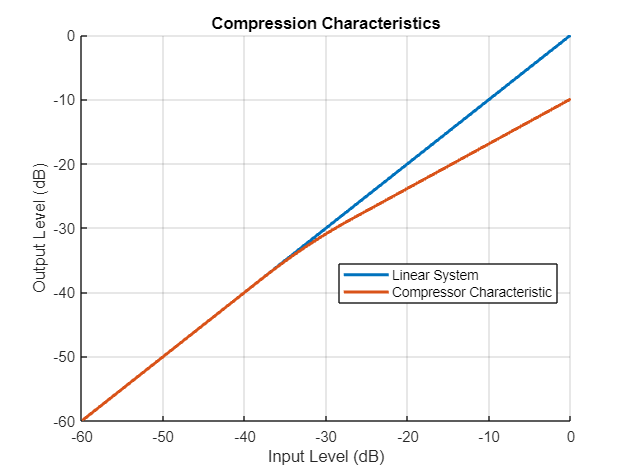

% Creating an audio dynamic range compressor object
% and passing in the parameters
threshold = -32.54;
knee = 10.89;
attack = 0.13;
release = 0.19;
makeupGainAuto = true;
makeupGain =3.95;

% adding the ratio value as this was not needed on limiters
ratio = 1.44;

adrc = AudioDynamicRangeCompressor( ...
    threshold, ...
    ratio, ...
    knee, ...
    attack, ...
    release, ...
    makeupGainAuto, ...
    makeupGain);

% Plotting the static characteristic of the compressor object
plotStaticCharacteristic(@adrc.applyStaticCharacteristic);

The audio input signal can then be passed into the process method to apply the compression.

A plot is then produced to show this compression effect.

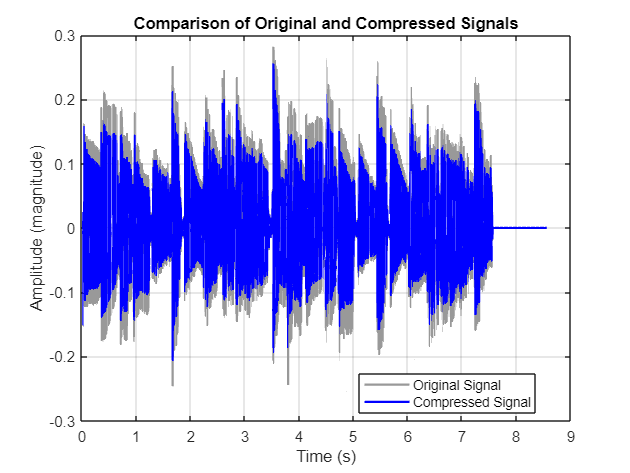

% Passing in the input signal to the process method of the audio rynamic
% range compressor object
[y, g] = adrc.process(x, fs);

% Plotting the time domain of the dry and wet signal
plotTimeDomainSignals(x, y, fs);

Again we can plot the gain computer of this process to see how the gain is calculated

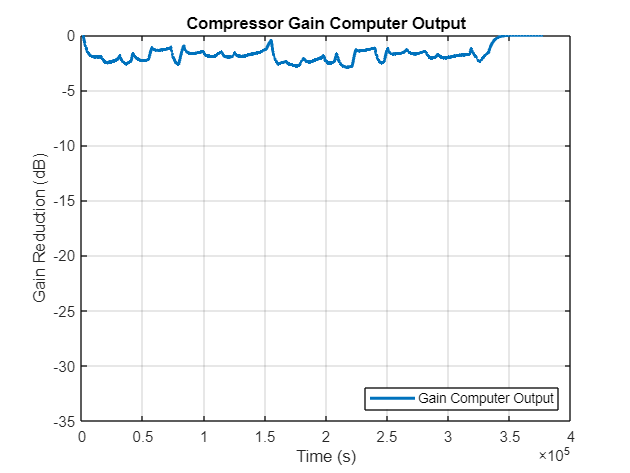

% Plotting the gain computer of the compressor
plotGainComputer(g);

#### Playing the audio

Press play to hear the original signal.

 
sound(x, fs);

Press play to hear the compressed signal.

 
sound(compressed_audio, fs);

## **Expander**

Expanders do the opposite of compression, increasing the dynamic range of an audio signal by attenuating low-amplitude components while leaving higher-amplitude components relatively unaffected, enhancing the perceived loudness and clarity of quieter parts in the audio signal.

### Parameters

**Range (Expansion Range)**

The range parameter in an expander controls the degree of expansion applied to the signal below the threshold. It determines how much the softer parts of the audio will be allowed to increase in volume.

**Expander/Gate Mode**

Some expanders have a mode switch that allows users to switch between expander and gate modes. In gate mode, the expander functions more like a traditional noise gate, completely attenuating signals below the threshold.

### Equations

Below demonstrates how to modify the equations shown above to apply the ratio value in the static characteristic calculation on the gain computer section for an expander:


$$x_{\mathrm{sc}}\left(x_{\mathrm{dB}}\right)=\left\{\begin{array}{cc}
T + (x_{\mathrm{dB}}-T) \times R & x_{\mathrm{dB}}<\left(T-\frac{W}{2}\right) \\
x_{\mathrm{dB}}+\frac{\left(1-R\right)\left(x_{\mathrm{dB}}-T+\frac{W}{2}\right)^2}{2 W} & \left(T-\frac{W}{2}\right) \leq x_{\mathrm{dB}} \leq\left(T+\frac{W}{2}\right) \\
x_{\mathrm{dB}} & x_{\mathrm{dB}}>\left(T+\frac{W}{2}\right)
\end{array},\right.$$


The same applies for the hard knee equation, applying the ratio value for an expander:


$$x_{\mathrm{sc}}\left(x_{\mathrm{dB}}\right)=\left\{\begin{array}{cl}
T + (x_{\mathrm{dB}}-T) \times R & x_{\mathrm{dB}}<T \\
x_{\mathrm{dB}} & x_{\mathrm{dB}} \geq T
\end{array}\right.$$


The interpolation smoothing filter applied to the gin reduction is also modified for an expander:


$$g_{\mathrm{s}}[n]= \begin{cases}\alpha_{\mathrm{A}} g_{\mathrm{s}}[n-1]+\left(1-\alpha_{\mathrm{A}}\right) g_c[n], & (C_{\mathrm{A}} > T_{\mathrm{H}}) \& (g_{\mathrm{c}}[n] \leq g_{\mathrm{s}}[n-1]) \\
g_s[n-1], & C_{\mathrm{A}} \leq T_{\mathrm{H}} \\
\alpha_{\mathrm{R}} g_{\mathrm{s}}[n-1]+\left(1-\alpha_{\mathrm{R}}\right) g_c[n], & g_{\mathrm{c}}[n]>g_{\mathrm{s}}[n-1]\end{cases}$$


### Applying the expander

Passing the parameters into the expander object, then plotting the static characteristic of the expander.

% Creating an audio dynamic range expander object and passing in the
% parameters
threshold = -27.77;
ratio = 2.3;
knee = 10.89;
attack = 0.13;
release = 0.19;
makeupGainAuto = true;
makeupGain =3.95;

% Adding the hold parameter as this is not needed on the above effects
hold = 1.12;

adre = AudioDynamicRangeExpander( ...
    threshold, ...
    ratio, ...
    knee, ...
    hold, ...
    attack, ...
    release, ...
    makeupGainAuto, ...
    makeupGain);

% Plotting the static characteristic of the expander object
plotStaticCharacteristic(@adre.applyStaticCharacteristic);

The code below applies the expansion onto the audio and plots the input against the output in the time domain to show the difference.

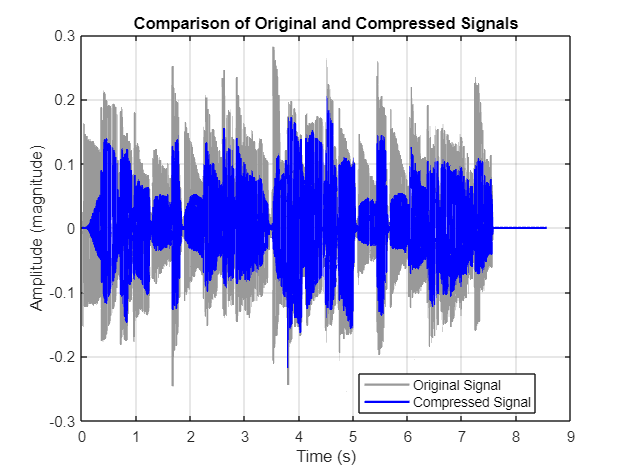

% Passing the input signal through the process method
[compressed_audio, g] = adre.process(x, fs);

% Plotting the expanded audio over the original
plotTimeDomainSignals(x, compressed_audio, fs);

The plot below shows the gain reduction of the expander

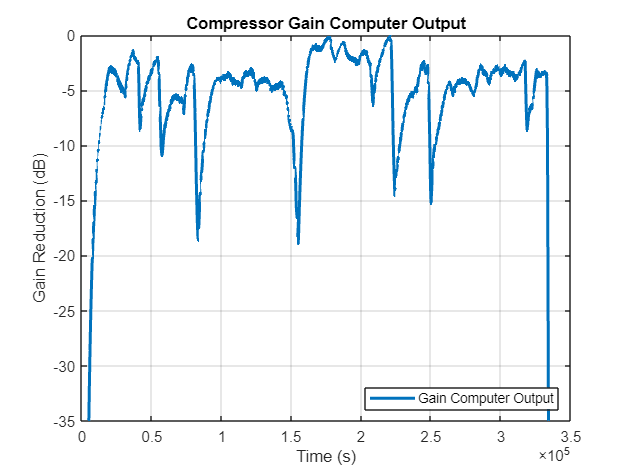

% Plotting the gain reduction
plotGainComputer(g);

#### Playing the audio

Press play to hear the original signal.

 
sound(x, fs);

Press play to hear the compressed signal.

 
sound(compressed_audio, fs);

## Noise Gates

Noise gates are used to suppress or eliminate unwanted background noise in audio recordings by automatically attenuating or muting audio signals that fall below a set threshold level.

### Parameters

**Hold Time**

The hold time parameter in a noise gate determines how long the gate remains open after the signal falls below the threshold. It helps prevent the gate from closing immediately after the input signal drops below the threshold, avoiding unnatural and abrupt cutoffs.

**Release Time (or Release Hold)**

This controls the time it takes for the gate to close after the hold time has elapsed. A longer release time can result in a smoother closure of the gate, preventing any artifacts or clicks in the audio.

**Sidechain Filter**

Some noise gates include a sidechain filter that allows you to filter the detection signal. This can be useful for fine-tuning which frequencies trigger the gate, helping to avoid unwanted gating effects on specific elements of the audio.

### Equations

The noise gate works with linear values and calculates the gain reduction in magnitude, therefore the absolute value is taken of the signal to get the gain.


$$x_a \left\lbrack n\right\rbrack =\left|x\left\lbrack n\right\rbrack \right|$$


This then passes through the gain computer and applies the static characteristic, working in magnitude values ($T_{\textrm{lin}}$ is the threshold in linear gain):


$$g_c \left(x_a \right)=\left\lbrace \begin{array}{ll}
0 & x_a <T_{\textrm{lin}} \\
1 & x_a \ge T_{\textrm{lin}} 
\end{array}\right.$$


The gain smoothing is applied the same way the expansion applies the interpolation:


$$g_{\mathrm{s}}[n]= \begin{cases}\alpha_{\mathrm{A}} g_{\mathrm{s}}[n-1]+\left(1-\alpha_{\mathrm{A}}\right) g_c[n], & (C_{\mathrm{A}} > T_{\mathrm{H}}) \& (g_{\mathrm{c}}[n] \leq g_{\mathrm{s}}[n-1]) \\
g_s[n-1], & C_{\mathrm{A}} \leq T_{\mathrm{H}} \\
\alpha_{\mathrm{R}} g_{\mathrm{s}}[n-1]+\left(1-\alpha_{\mathrm{R}}\right) g_c[n], & g_{\mathrm{c}}[n]>g_{\mathrm{s}}[n-1]\end{cases}$$


These gain reduction values are then applied to the input signal:


$$y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack \times g_s \left\lbrack n\right\rbrack$$


Below shows a basic diagram of how these equations are applied and where the parameters are used:

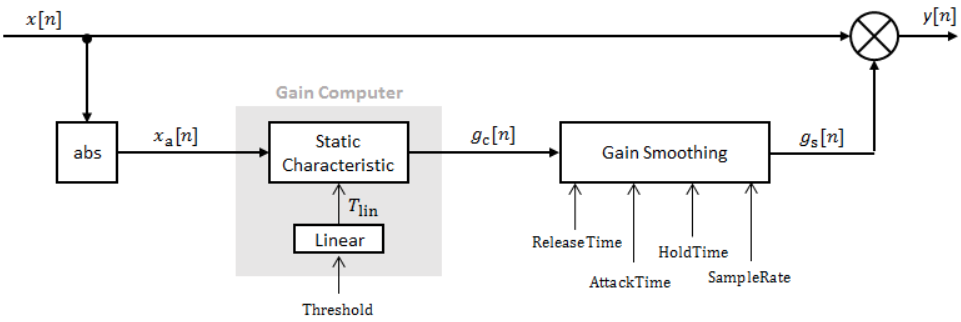

### Applying the noise gate

Passing the parameters into the noise gate object, then plotting the static characteristic of the noise gate.

% Creating an audio dynamic range noise gate object and passing in the
% parameters

% Shorter time coefficients can cause distortion due to the drastic
% amplitude changes
threshold = -30.6;
hold = 0.14;
attack = 0.06;
release = 0.04;

ang = AudioNoiseGate( ...
    threshold, ...
    hold, ...
    attack, ...
    release);

% Plotting the static characteristic of the noise gate object
plotStaticCharacteristic(@ang.applydBStaticCharacteristic);

The code below applies the gate onto the audio and plots the input against the output in the time domain to show the difference.

A sidechain parameter can also be passed into the process method of these compression classes, this will apply a sidechain signal to control the gain reduction of the input signal.

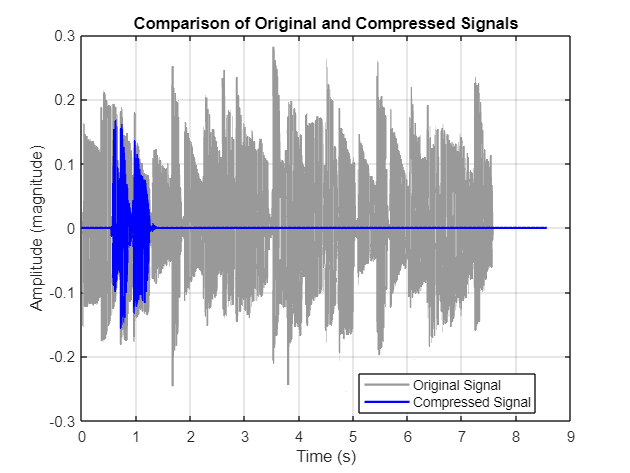

% Getting the sidechain signal
[sidechain, fs] = audioread("audio\hee_hee.wav");
sidechain = sidechain(:, 1)';  % transposing the audio so it's the correct dimention, and making the audio mono
sidechain(numel(x)) = 0;       % padding the sidechain input so it's the same dimentions as the input signal

% Passing the input signal through the process method
[compressed_audio, g] = ang.process(x, fs, sidechain);

% Plotting the expanded audio over the original
plotTimeDomainSignals(x, compressed_audio, fs);

The plot below shows the gain reduction of the noise gate

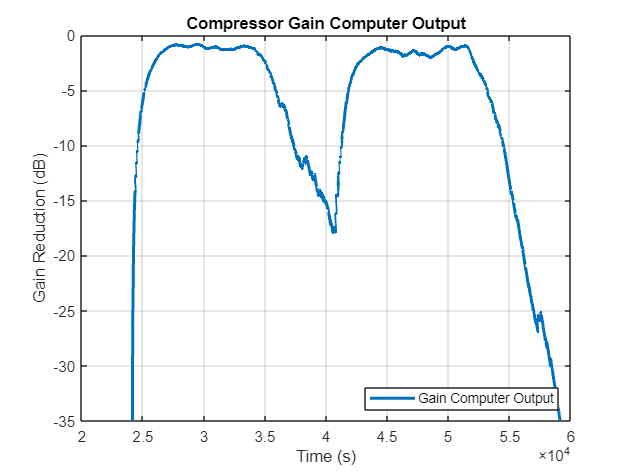

% Plotting the gain reduction
plotGainComputer(g);

#### Playing the audio

Press play to hear the original signal.

 
sound(x, fs);

Press play to hear the compressed signal.

 
sound(compressed_audio, fs);

## Upwards Compression

Upwards compression increases the volume of softer sounds while maintaining the overall dynamic range, enhancing clarity and bringing out subtle details in the audio signal.

### Parameters

**Threshold (Inverted)**

In upwards compression, the threshold is often inverted. Instead of compressing signals that exceed the threshold, it boosts signals that fall below it. This is used to enhance softer elements in the audio without affecting louder portions.

**Ratio (Expansion Ratio)**

While traditional compression reduces the dynamic range, upwards compression increases it. The expansion ratio controls the amount by which softer sounds are boosted. A higher expansion ratio results in more aggressive upwards compression.

## **Multiband Compressor**

Multiband compressors split the audio signal into multiple frequency bands, allowing independent compression of each band to effectively control and balance the dynamics of different frequency ranges in a mix.

### Parameters

**Crossover Frequencies**

In a multiband compressor, the audio signal is divided into different frequency bands. Crossover frequencies determine the points at which the signal is split into these bands. Users can often adjust the crossover frequencies to target specific frequency ranges for compression.

**Bandwidth (Q Factor)**

The bandwidth or Q factor in a multiband compressor controls the width of each frequency band. A higher Q factor narrows the band, affecting a smaller range of frequencies, while a lower Q factor broadens the band.

**Threshold, Ratio, Attack, Release for Each Band**

Multiband compressors typically have separate controls for each frequency band, allowing precise adjustment of compression settings for different parts of the spectrum. This enables tailored dynamic control across various frequency ranges.

## Appendicies

When applying compression in a real-time scenario, samples will have to be stored in a circular buffer to calculate accurate RMS values.

Below is example code of how this would be done using a Compressor class and CircularBuffer class.

## References

Brown, G. (2021). *Audio Dynamics 101: Compressors, Limiters, Expanders, and Gates*. [online] Available at: [https://www.izotope.com/en/learn/audio-dynamics-101-compressors-limiters-expanders-and-gates.html](https://www.izotope.com/en/learn/audio-dynamics-101-compressors-limiters-expanders-and-gates.html) [Accessed 13 Dec. 2023].

Carter, S. (2022) *What is Compression? (Compression in Music Overview). *[online] Music Mix Pro. Available at: [https://musicmixpro.co.uk/what-is-compression/#:~:text=Well%2C%20their%20origins%20started%20in,to%20distort%2C%20and%20possibly%20fail](https://musicmixpro.co.uk/what-is-compression/#:~:text=Well%2C%20their%20origins%20started%20in,to%20distort%2C%20and%20possibly%20fail) [Accessed: 11 Dec. 2023].

Cherubini, P. (2022). *A brief history of dynamics processors. *[online] Age of Audio. Available at: [https://www.ageofaudio.com/en/brief-history-of-dynamics-processors/](https://www.ageofaudio.com/en/brief-history-of-dynamics-processors/) [Accessed: 10 Dec. 2023].

Fox, A. (2021a) *What Is An Optical Compressor & How Does It Work?* [online] My New Microphone. Available at: [https://mynewmicrophone.com/what-is-an-optical-compressor-how-does-it-work/](https://mynewmicrophone.com/what-is-an-optical-compressor-how-does-it-work/) [Accessed 13 Dec. 2023].

Fox, A. (2021b). *What Is A FET Compressor & How Does It Work?* [online] My New Microphone. Available at: [https://mynewmicrophone.com/what-is-a-fet-compressor-how-does-it-work/](https://mynewmicrophone.com/what-is-a-fet-compressor-how-does-it-work/) [Accessed 13 Dec. 2023].

McCoy, T. (2022). *Tube Versus Solid-State Compressor Basics | Universal Audio*. [online] Available at: [https://www.uaudio.com/blog/tube-v-solid-state-compressors/](https://www.uaudio.com/blog/tube-v-solid-state-compressors/) [Accessed 13 Dec. 2023].

Paquis, M. (2023). *Variable Mu Compression: How it Works and When to Use it - Pulsar Audio Plugins*. [online] Pulsar Audio Plugins. Available at: [https://pulsar.audio/blog/variable-mu-compression-how-it-works-and-when-to-use-it/](https://pulsar.audio/blog/variable-mu-compression-how-it-works-and-when-to-use-it/) [Accessed 13 Dec. 2023].

Somich, J. (2018). *A History of Audio Processing Part 2 – Automatic Processing Starts*. [online] The Broadcasters Desktop Resource. Available at: [https://www.thebdr.net/a-history-of-audio-processing-part-2-automatic-processing-starts/](https://www.thebdr.net/a-history-of-audio-processing-part-2-automatic-processing-starts/) [Accessed 13 Dec. 2023].

Soundbridge.io. (2023). *VCA Compressor*. [online] Available at: [https://www.soundbridge.io/vca-compressor](https://www.soundbridge.io/vca-compressor) [Accessed 13 Dec. 2023].

Vincent, S. (2012). *The Beginner’s Guide to Compression*. [online] Music & Audio Envato Tuts+. Available at: [https://music.tutsplus.com/the-beginners-guide-to-compression--audio-953t](https://music.tutsplus.com/the-beginners-guide-to-compression--audio-953t) [Accessed 9 Dec. 2023].

Zölzer, U. (2011) *DAFX. 2nd edn. Wiley*. [online] Available at: [https://www.perlego.com/book/1013495/dafx-digital-audio-effects-pdf](https://www.perlego.com/book/1013495/dafx-digital-audio-effects-pdf) [Accessed: 14 Oct. 2022].

## Bibliography

Mathworks.com. (2023). Compressor. [online] Available at: [https://uk.mathworks.com/help/audio/ref/compressor.html](https://uk.mathworks.com/help/audio/ref/compressor.html) [Accessed 14 Dec. 2023].

Mathworks.com. (2023). Limiter. [online] Available at: [https://uk.mathworks.com/help/audio/ref/limiter.html](https://uk.mathworks.com/help/audio/ref/limiter.html) [Accessed 14 Dec. 2023].

Mills, J. (2022). *How Analog Plugin Emulations Work (& Are They Better Than Digital?)*. [online] Producer Hive. Available at: [https://producerhive.com/ask-the-hive/how-do-analog-plugin-emulations-work/](https://producerhive.com/ask-the-hive/how-do-analog-plugin-emulations-work/) [Accessed 13 Dec. 2023].

Musictechstudent.co.uk. (2013). *History and Development of Compression - Music Tech Student*. [Online] Available at: [https://musictechstudent.co.uk/music_technology_/history-and-development-of-compression/](https://musictechstudent.co.uk/music_technology_/history-and-development-of-compression/) [Accessed 9 Dec. 2023].

‌